# Load CSV Measurement Data

%Zu importierende Datei auswählen
filename = "DC8/varX300DC8_2"

filename = "DC8/varX300DC8_2"

%filename = "DC8/varTheta3DC8_1";
%Importieren und nicht relevante Informationen entfernen
data = readtable(filename);
data([1:17],:)=[];

taskTime = 10e-3; %10ms

## durchschn. Kameraverzögerung berechnen

cnt = 1;
countTimesteps=0;
oldCamX = 0;
cntCamX = zeros(height(data),1)

cntCamX =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


cntCamX = cntCamX -1;   %Alle Elemente auf -1 setzen
for row = 1 : height(data)
    camXd = data{row,"camX"};
    if camXd == oldCamX
        cntCamX(cnt)= cntCamX(cnt)+1;
    else
        cnt = cnt +1;
    end
    oldCamX = camXd;
end



% Entfernen von nicht benötigten Indizes und hohen Werten durch Warten zu Beginn der Messung (dort noch keine Kameradaten)
Idx_neg = cntCamX < 0;  % finding X indices corresponding to negative elements
cntCamX ( Idx_neg   ) = [];  % removing elements using [] operator

Idx_neg = cntCamX > 20;  % finding cntCamX indices corresponding to elements above 20
cntCamX ( Idx_neg   ) = [];  % removing elements using [] operator

% alle Element um 1 erhöhen, da bei -1 gestartet
cntCamX = cntCamX+1;
% Durschnitliche Zyklenazahl berechnen neue Kamerawerte erhalten
delay = mean(cntCamX)

delay = 4.1520

## ECHTES DELAY SIEHE SINUSFAHRT OBIGE BERECHNUNG nicht delay sondern nur Kameramessfrequenz


delay = 14;

## Kameradaten filtern

## Nullen aus Kameradaten entfernen

camThetaFilt = zeros(height(data),1);
oldCamTheta = 0;
for row = 1 : height(data)
    camThetaFilt(row) = data{row,"camTheta"};
    if camThetaFilt(row) == 0
        camThetaFilt(row) = oldCamTheta;
    else 
        oldCamTheta = camThetaFilt(row);
    end
end


## Encoderdaten filtern

## Koordinatentransformation RoboterKS auf GlobalKS

% Delay auf naechst hoeheren Ganzzahlwert runden und um entsprechendes
% Delay versetze Kamerdaten (Theta) für Transformation nutzen
xTf = zeros(height(data),1);
yTf = zeros(height(data),1);
Theta = zeros(height(data),1);
pose = zeros(3,1);

vXWorld = zeros(height(data),1);
vYWorld = zeros(height(data),1);
vThetaWorld = zeros(height(data),1);
vRobotKS = zeros(3,1);
vWorldKS = zeros(3,1);

XWorld = zeros(height(data),1);
YWorld = zeros(height(data),1);

for row = 1 : height(data)-delay
    %Theta(row) = data{row+5,"camTheta"}
    Theta(row) = camThetaFilt(row+delay);

    % Theta aus Grenzen von [-pi;pi] in [0;2pi] transformieren
 %   if Theta(row) > pi
%        Theta(row) = Theta(row) - 2 * pi;
%    elseif Theta(row) < -pi
  %      Theta(row) = Theta(row) + 2 * pi;
  %  end

    pose= [data{row,"distX"}; data{row,"distY"}; data{row,"distTheta"}];
    TMat = [cos(-Theta(row)),-sin(-Theta(row)),0;sin(-Theta(row)),cos(-Theta(row)),0;0,0,1];
    pose= TMat * pose;
    xTf(row) = pose(1);
    yTf(row) = pose(2);

    vRobotKS = [data{row, "vXFromMotor"}; data{row, "vYFromMotor"}; data{row, "vThetaFromMotor"}] ;
    vWorldKS = TMat * vRobotKS;
    vXWorld(row) = vWorldKS(1);
    vYWorld(row) = vWorldKS(2);
    vThetaWorld(row) = vWorldKS(3);

    % Odometrie
    if row > 1
        XWorld(row)= XWorld(row-1) + vXWorld(row)*taskTime;
    end
end


## Plotten der Berechnungen

% Plot x-Koordinatenverlauf nach Odomterie, transformeirter Odo vs Kamera
distX=data(:,"distX")

distX = 1146×1 table
    distX
    _____

      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  


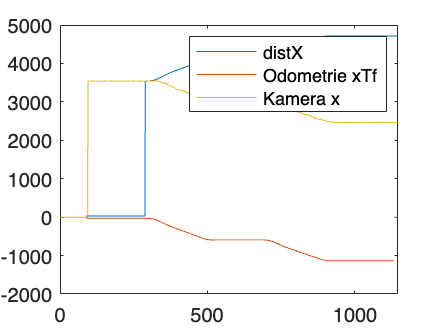

distX=table2array(distX);
plot(distX); hold on;
plot(XWorld); hold on;

%plot(xTf);

camX=data(:,"camX");
camX=table2array(camX);
plot(camX); hold off;
legend("distX","Odometrie xTf","Kamera x");

%legend("XWorld","Kamera x");